# Try different index for winner-take-all

clear;
clc;
addpath('..\funcs');
load ..\..\data\all_0_0.5_0_0.05_Iattn_0.02.mat;

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 200;

Iattn = 0.02;

n = 1:200;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);
sz = 4;
steps = size(orderSheet,1);

## Envelop of firing rate

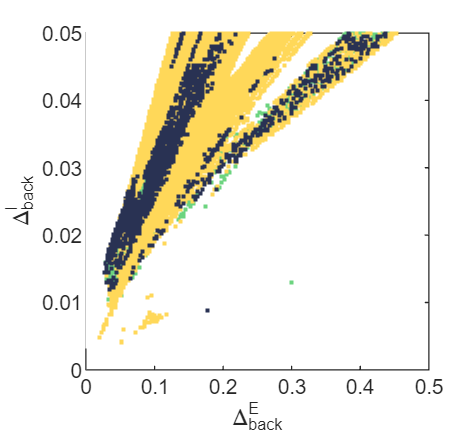

anti_WTA_sens = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,2) < levelSheet(i,j,3)
            anti_WTA_sens(i,j) = 1;
        end
    end
end

anti_WTA_attn = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if levelSheet(i,j,5) < levelSheet(i,j,6)
            anti_WTA_attn(i,j) = 1;
        end
    end
end

anti_WTA_sens = anti_WTA_sens == 1;
anti_WTA_attn = anti_WTA_attn == 1;

figure();
for i = 1:steps
    x = Delta_e(anti_WTA_sens(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#6cd47f"); % 
    hold on;
end

for i = 1:steps
    x = Delta_e(anti_WTA_attn(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#ffd859"); %
    hold on;
end

anti_WTA_both = anti_WTA_sens .* anti_WTA_attn;
anti_WTA_both = anti_WTA_both == 1;
for i = 1:steps
    x = Delta_e(anti_WTA_both(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#293253"); %
    hold on;
end

% STY-STY
roi = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if orderSheet(i,j) ~= -1 && sum(osciSheet(i,j,2,:)==1)<5
            roi(i,j) = 1;
        end
    end
end

roi = roi == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'s','filled',"MarkerFaceColor","#FFFFFF"); % white: stationary
    hold on
end

xlabel("\Delta_{back}^{E}");
ylabel("\Delta_{back}^{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
box on;
xticks([0 0.1 0.2 0.3 0.4 0.5]);
yticks([0 0.01 0.02 0.03 0.04 0.05]);

x0 = 0; y0 = 0; width = 6.5; height = 6;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);

figure()
s1 = scatter(1,1,'s','filled',"MarkerFaceColor","#EA4335"); % red
hold on
s2 = scatter(1,2,'s','filled',"MarkerFaceColor","#FBBC05"); % yellow
s3 = scatter(1,2,'s','filled',"MarkerFaceColor","#34A853"); % green
s4 = scatter(1,2,'s','filled',"MarkerFaceColor","#4285F4"); % blue
s5 = scatter(1,2,'s','filled',"MarkerFaceColor",[209 211 212]/256); % grey
whitebg([1 1 1]);

lgd = legend([s1 s2 s3 s4 s5],["In order", "In order with \beta","Not in order", "Stationary","Inf"]);
legend boxoff  
lgd.FontName = 'Arial';
set(gca, 'FontName', 'Arial');
set(gca,'FontSize',8);
x0 = 0; y0 = 0; width = 9; height = 8;
set(gcf,'units','centimeters','position',[x0,y0,width,height]);
print('planeLegend', '-dpng', '-r600');
print('planeLegend', '-dsvg', '-r600');
print('planeLegend', '-dpdf', '-r600');

## Integral over one cycle